# Dataset Analyzer from FHD Haptic Perception Experiment

This matlab livescript anlyzes and saves the data related to the Haptic Perception experiment with FHD

## Enablers

clear all; close all; clc;
addpath("\path\to\data_source");
savefigs=false;

## Aggregate Dataset results

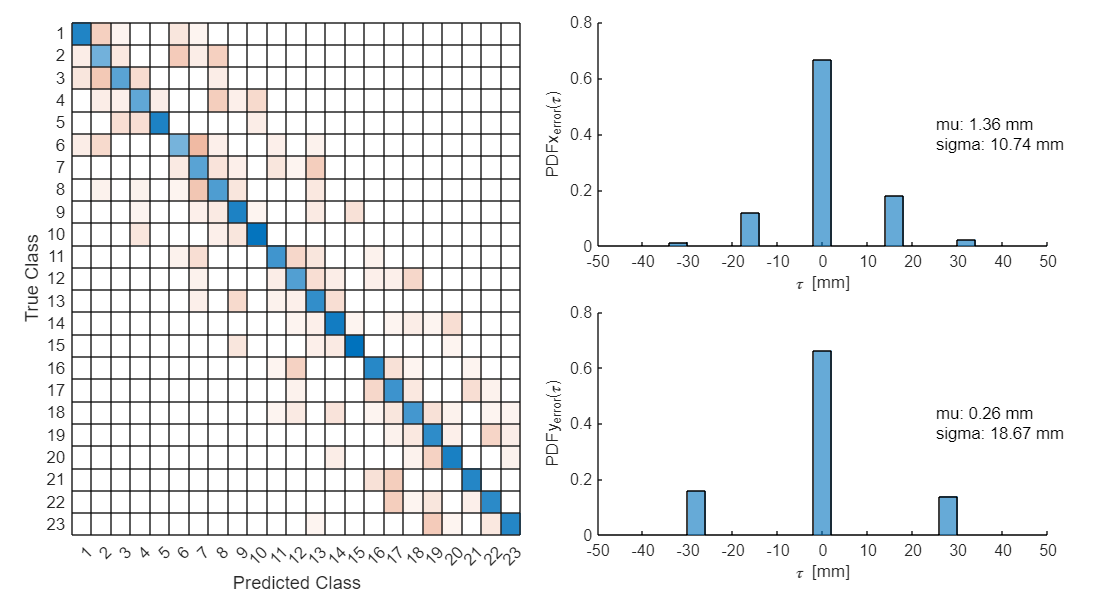

load Indentations;
C=zeros(23,23);
Es=[];
for i=1:14
    
    %subject
    Si=sprintf("S%d",i);
    
    %get confusion mat
    Ci=computeconfusion(Indentations,Si);
    C=C+Ci;

    %get distribution
    Esi=computedistribution(Indentations,Si);
    Es=[Es; Esi];
end


%compute the RMSE
distances=vecnorm(Es,2,2);
SEs=vecnorm(Es,2,2).^2;
RMSE=sqrt(mean(SEs));

%compute the single drift percent
drifts=uniquetol(distances,0.1,"highest");
singledrift=drifts(2);
percent_inside_1=100*length(find(distances<=singledrift))/length(distances);

%show
fig=figure('Position',[170 50 880 480]);
T=tiledlayout(1,2,"TileSpacing","compact","Padding","compact");

%show confusion mat
nexttile(T);
acc =100*sum(diag(C))/sum(C(:));
confusionchart(C); 
% title(sprintf('Accuracy: %.2f %%',acc));

%show distribution
binwidth=4;
t=tiledlayout(T,2,1,"TileSpacing","compact","Padding","compact");
t.Layout.Tile = 2;
% title(t,sprintf("RMSE: %.2f mm, Single Drift: %.2f %%",RMSE,percent_inside_1));

nexttile(t);
hold on;
E=Es(:,1);
h1=histogram(E,'BinWidth',binwidth,"Normalization","probability");
h1.BinEdges=h1.BinEdges-binwidth/2;
text(25,0.4,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFx_{error}(\tau)'); xlim([-50 50]); xticks(-50:10:50);

nexttile(t);
hold on;
E=Es(:,2);
h2=histogram(E,'BinWidth',binwidth,"Normalization","probability");
h2.BinEdges=h2.BinEdges-binwidth/2;
text(25,0.4,sprintf("mu: %.2f mm \nsigma: %.2f mm",mean(E),std(E)),'FontSize',10);
hold off; xlabel('\tau [mm]'); ylabel('PDFy_{error}(\tau)'); xlim([-50 50]);xticks(-50:10:50);

## Single Subjects results

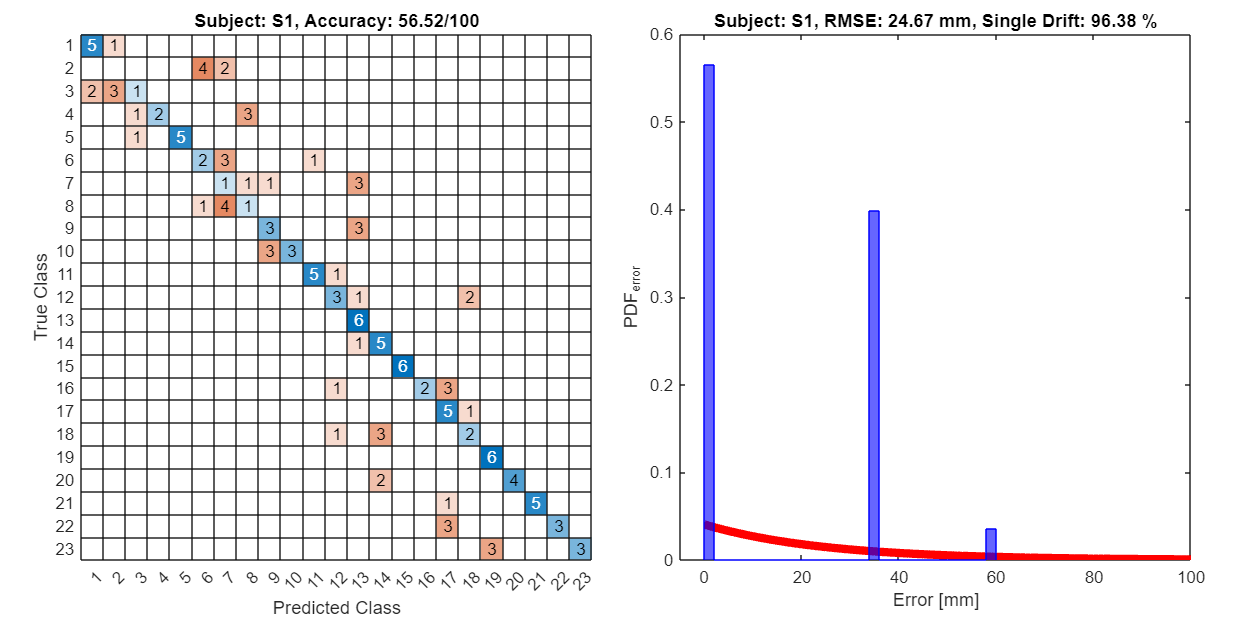

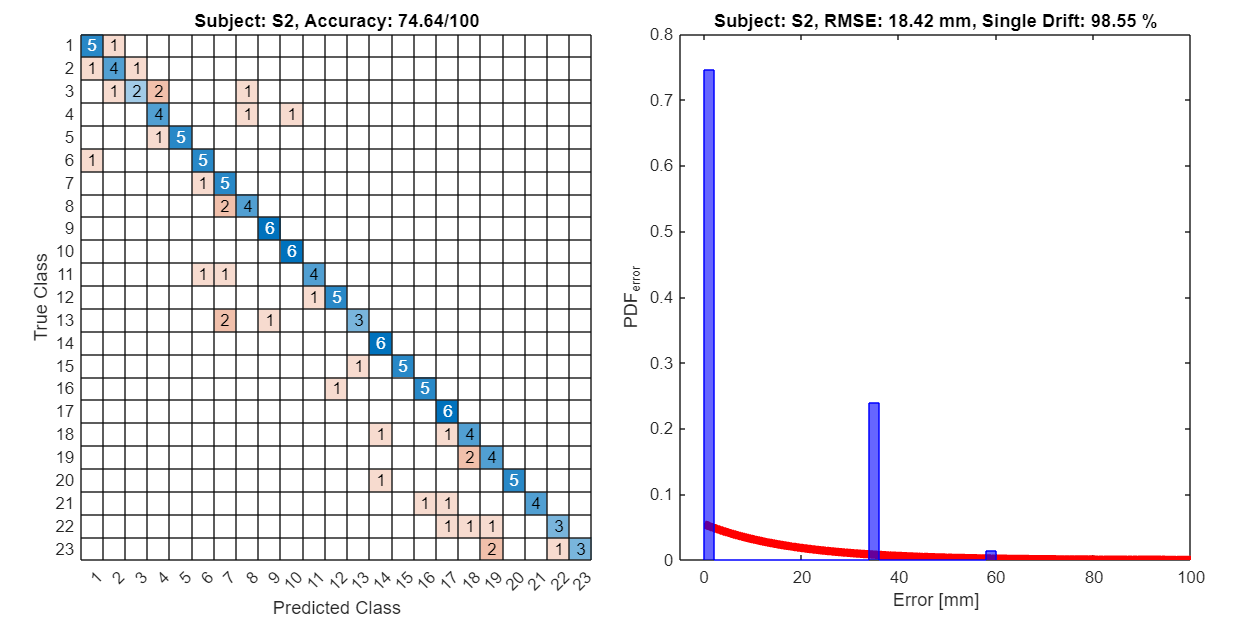

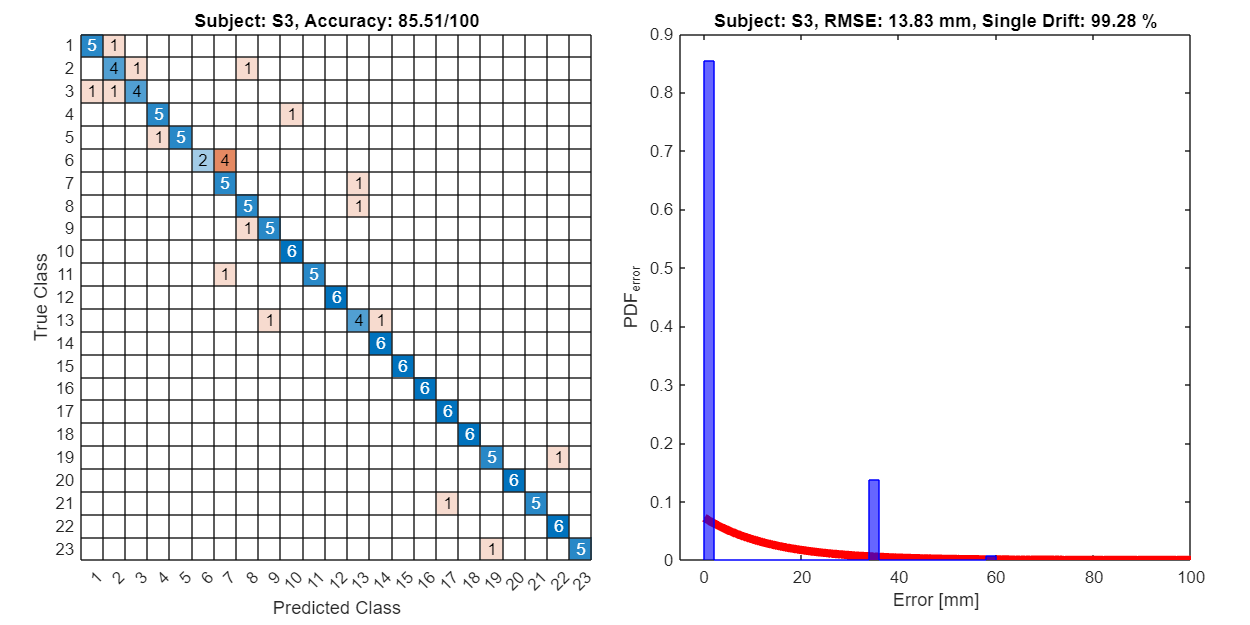

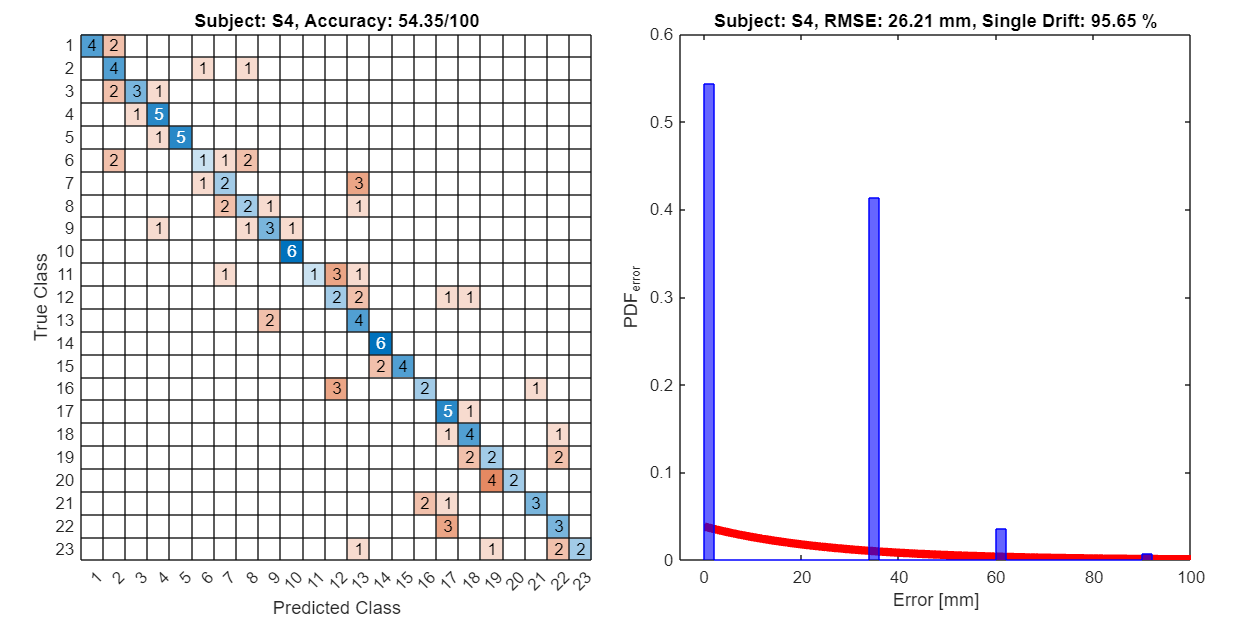

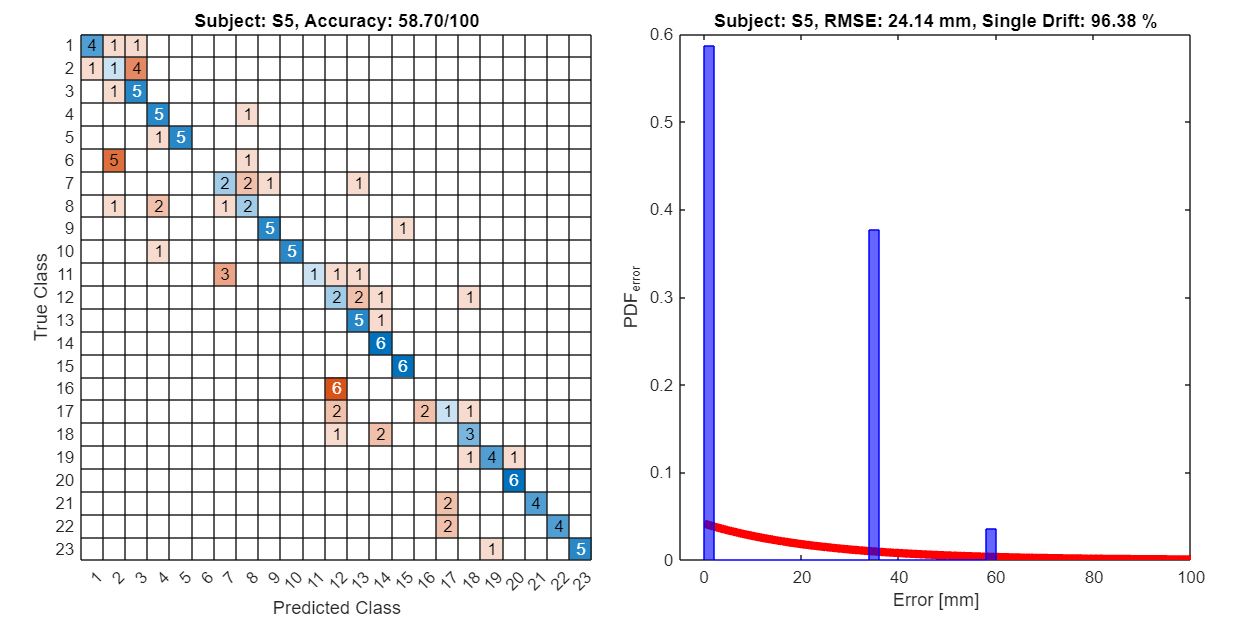

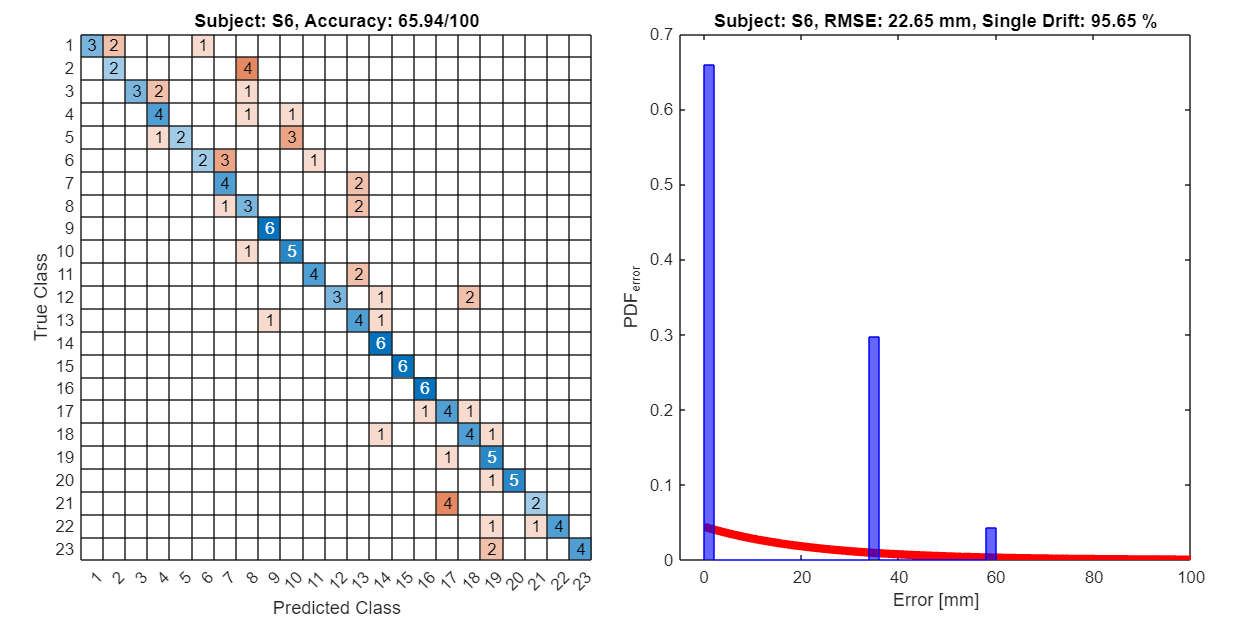

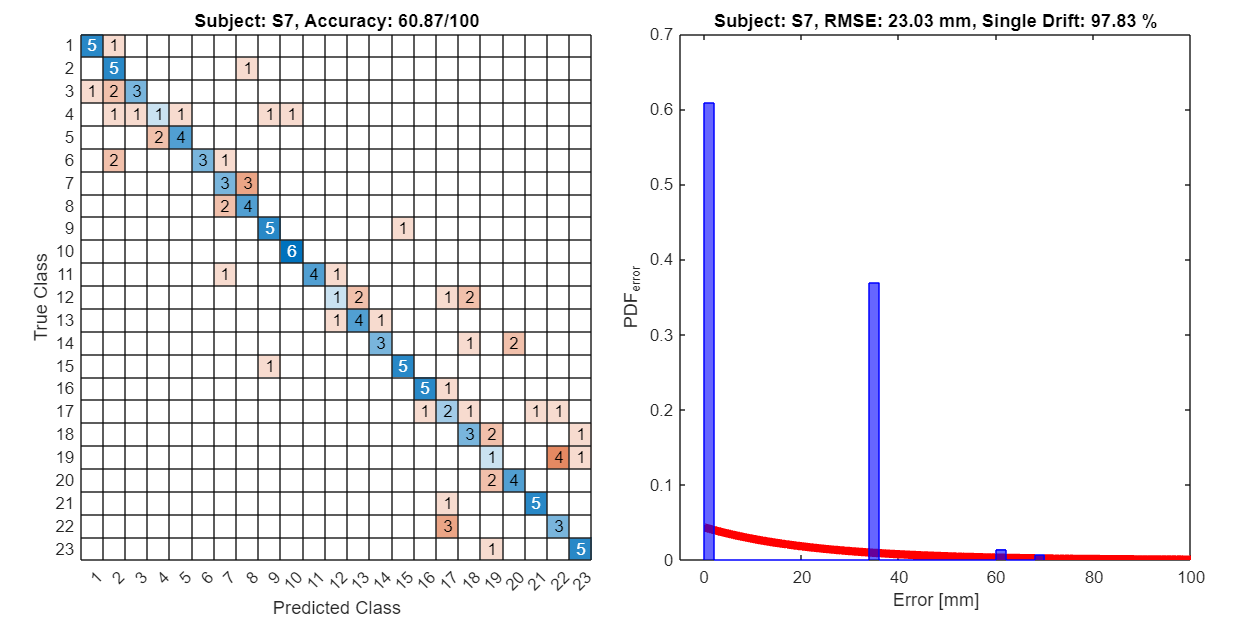

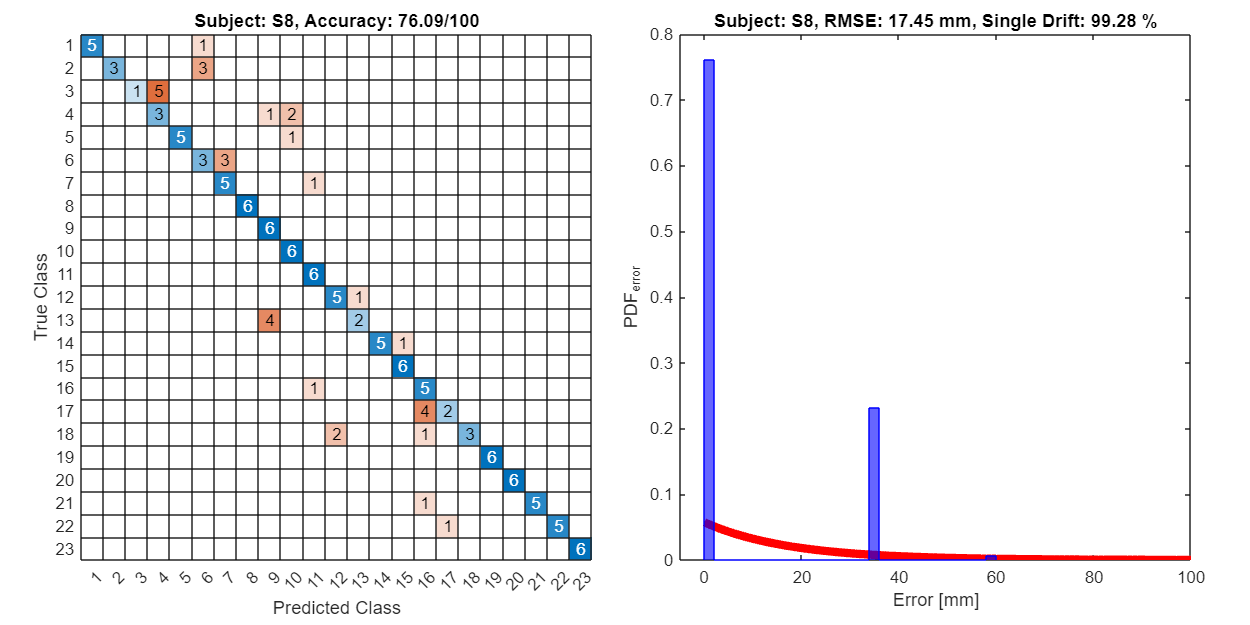

load Indentations;

for i=1:14
    
    %subject
    Si=sprintf("S%d",i);
    
    %get confusion mat
    C=computeconfusion(Indentations,Si);

    %get distribution
    distances=computedistribution(Indentations,Si);

    %create fig
    fig=figure('Position',[100,100,1000,500]);
    tiledlayout(1,2,"TileSpacing","compact","Padding","compact");
    
    %show confusion mat
    nexttile;
    acc =100*sum(diag(C))/sum(C(:));
    confusionchart(C); title(sprintf('Subject: %s, Accuracy: %.2f/100',Si,acc));
    
    %show error dist
    RMSE=sqrt(mean(distances.^2));
    nexttile;
    plot(0:100,exppdf(0:100,RMSE),"Color",'r','LineWidth',5); hold on;
    h=histogram(distances,'BinWidth',2,'Normalization','probability','FaceColor','b','EdgeColor','b'); xlim([-5 100]);
    hold off; xlabel('Error [mm]'); ylabel('PDF_{error}');
    percent=nonzeros(h.BinCounts/length(distances));
    percent_inside_1=100*sum(percent(1:2));
    title(sprintf('Subject: %s, RMSE: %.2f mm, Single Drift: %.2f %%',Si,RMSE,percent_inside_1));
    
    %save
    if savefigs
        saveas(fig,fullfile("Figures/",sprintf("Subject%s.png",Si)));
    end

end